## Tutorial: how to extract a STL file containing multiple objects into individual STL files

Suppose you are simulating some packing of particles. This could be used for fluid flow and heat transfer analysis in porous media, magnetic simulations of grains, some novel design and manufacturing technique etc. 

A possible workflow is to construct a *geometric* model in a 3D software; we'll cite [Blender](https://www.blender.org/) because this is what is used in the test files in this project. This very tutorial contains such a file, `all_particles`, which consists of circa 200 hexagonal prisms of different sizes and shapes.

**Note: currently, **`STLExtractor`** only supports extraction of hexagonal prisms. This could be extended in future releases.**

The main model for this package is called `STLExtractor`:

help STLExtractor

 STLExtractor Extract individual objects from an STL FILE
    Objects of this class can process an STL file and retrieve individual hexagonal
       prims. The goal is to extract individual "particles" from a "packing".

    Documentation for STLExtractor



To actually instantiate one, you need the name of the STL file you want to process and a directory where you want to save the individual files:

tutorialsDir = fileparts(which('Tutorial1_Extract'));
exampleFile = fullfile(tutorialsDir,"all_particles.stl");
outputDir = fullfile(tutorialsDir,"tmp");
% create folder if not existent
if ~isfolder(outputDir)
    mkdir(outputDir);
end

extractor = STLExtractor(exampleFile,outputDir);

Then, you call the `process` method:

l = extractor.process;

The returned object is an instance of `ExtractedPacking`, which represents exactly that: a *packing* of *items* that is *extracted* from an STL file that contains the whole packing, originally without identification of said items. 

Let's take a look at what whats inside this object. Notice that you get geometrical information and some descriptive statistics on the positiions and orientations of the items.

We use the term *alignment* to indicate the dot product of an item's normal vector with one of the corresponing axes.

disp(l);

  ExtractedPacking with properties:

                                     renderer: [1×1 PackingFigureRenderer]
                                        items: [1×184 HexagonalPrism]
                                         xmin: -2.4773
                                         xmax: 2.4976
                                         ymin: -2.4799
                                         ymax: 2.4777
                                         zmin: -2.4764
                                         zmax: 3.2090
                                           Lx: 4.9749
                                           Ly: 4.9577
                                           Lz: 5.6854
                                       volume: 140.2254
                    volumetricFillingFraction: 0.5060
                            averageAlignmentX: 0.0033
                  standardDeviationAlignmentX: 0.5247
              volumeWeightedAverage

Where you can see it recognized almost 200 prisms.

You can also plot a rendering of the items:

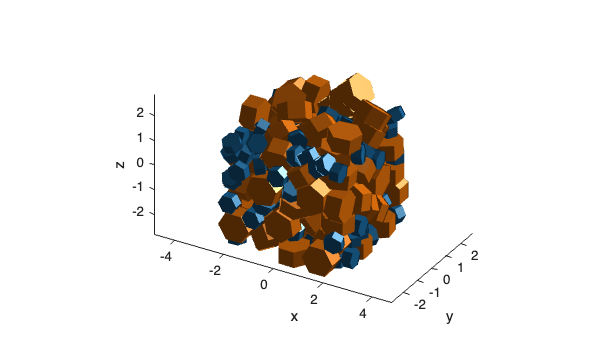

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [9.5779 7.3290 16.0000 9.0000]
       Units: 'centimeters'

  Show all properties


l.plot

### Cutoff procedures

A major feature of `STLExtractor` is the ability to *cut off* items from the raw extracted packing. There are three procedures currently implemented in `STLExtractor:`

#### Removing particles whose vertices surpass cut planes

In this first version, you specify a margin and a direction. For instance, in the example below, you specify cut planes 5% off from the maximum and minimum coordinates of the packing (totaling a total 10% margin, which is what is passed to the function), and any items with any vertices beyond that cut plane are removed:

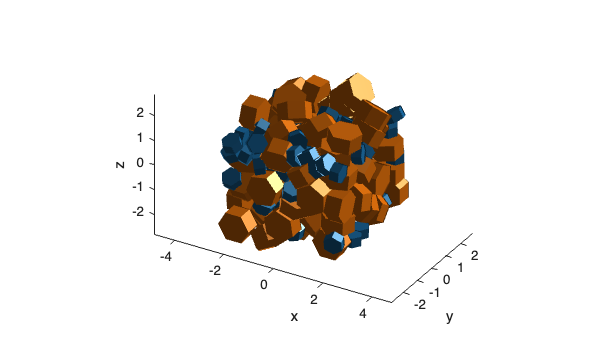

c1 = l.cutoff(0.1,"x","Method",CutoffMethod.vertices);
c1.plot;

#### Removing particles whose centers surpass cut planes

By changing the `"Method"` argument, only items whose *center points* surpass the cut planes are removed:

c2 = l.cutoff(0.1,"x","Method",CutoffMethod.centers);
c2.plot;

#### Removing particles only in the z-direction

In a third method, you can cut the packing only in the z-direction. With this method, `STLExtractor` will calculate the averages of the lengths of the packing in the x and y direction, and then will try to extract a packing with this length in the middle of the z-direction:

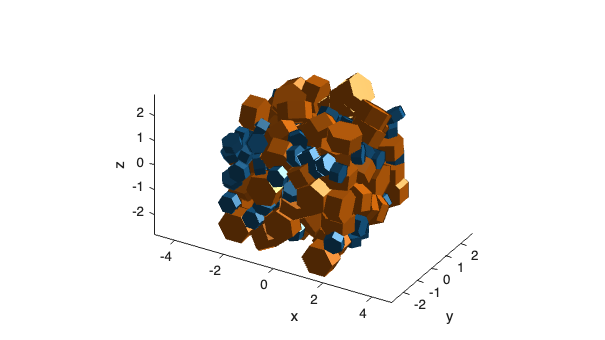

c4 = l.cutoffz("Method",CutoffMethod.vertices);
c4.plot;

c5 = l.cutoffz("Method",CutoffMethod.centers);
c5.plot;